**This is a SHM solver. The solver will plot the amplitude with time. **

%Declare symbolic variables
syms x(t) m k

%Compute force symbolically 
F = m*diff(x,t,2) == -k*x;
%Dx = diff(x,t);

%Solve system symbolically
Amp_sym = dsolve(F)

$$Amp\_sym = C_{1}\,{\mathrm{e}}^{\frac{t\,\sqrt{-k\,m}}{m}}+C_{2}\,{\mathrm{e}}^{-\frac{t\,\sqrt{-k\,m}}{m}}$$


%Convert symbolic system to numerical system
Amp_num = subs(Amp_sym, [sym('m'), sym('k') sym('C1'), sym('C2')], [10, 5, 1, 1] )

$$Amp\_num = {\mathrm{e}}^{-\frac{\sqrt{50}\,t\,\mathrm{i}}{10}}+{\mathrm{e}}^{\frac{\sqrt{50}\,t\,\mathrm{i}}{10}}$$

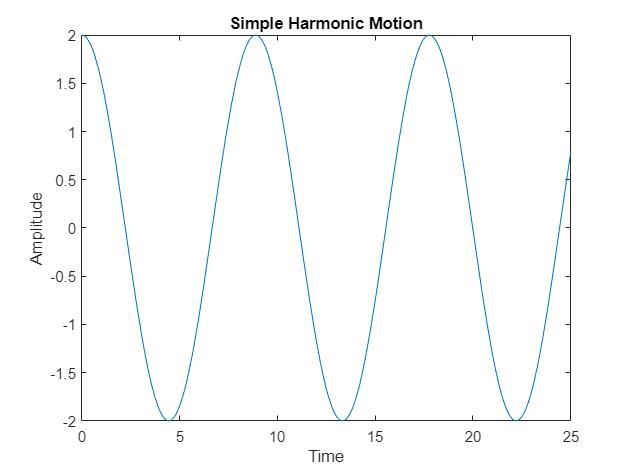


%Plot the solution
plot = fplot(Amp_num);
plot.XRange = [0 , 25];
title("Simple Harmonic Motion")
xlabel('Time');
ylabel('Amplitude')

**Simple Damped Oscillations:**

syms x(t) m k c

Dx = diff(x,t)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

Dx2 = diff(x,t,2)

$$Dx2(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

F = m*Dx2 == -k*x -c*Dx ;


%cond = [x(0) == 1, Dx(0) == 1];
Amp_sym = dsolve(F)

$$Amp\_sym = C_{2}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}+C_{1}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}$$


%Amp_num = matlabFunction(Amp_sym)

Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('C1'), sym('C2')], [10, 5, 0.5, 1, 1] )

$$Amp\_num = {\mathrm{e}}^{\frac{t\,\left(-\frac{1}{2}+\frac{\sqrt{799}\,\mathrm{i}}{2}\right)}{20}}+{\mathrm{e}}^{-\frac{t\,\left(\frac{1}{2}+\frac{\sqrt{799}\,\mathrm{i}}{2}\right)}{20}}$$

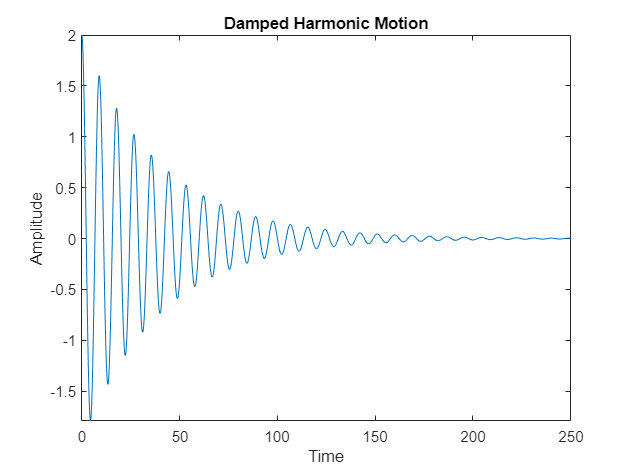

%pretty_equation(Amp)
plot = fplot(Amp_num);
plot.XRange = [0 , 250];
title("Damped Harmonic Motion")
xlabel('Time');
ylabel('Amplitude')

**Forced oscillations:**

syms x(t) m k c F0 omega

xMax = 200;
Dx = diff(x,t)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

Dx2 = diff(x,t,2)

$$Dx2(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

F = m*Dx2 + k*x + c*Dx == F0*sin(omega*t);


%cond = [x(0) == 1, Dx(0) == 1];
Amp_sym = dsolve(F)

$$Amp\_sym = \begin{array}{l} C_{2}\,\sigma_{3}+C_{1}\,\sigma_{2}+\frac{F_{0}\,\sigma_{3}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{4}}{2\,m}}\,\left(\sigma_{1}-\frac{\sin\left(\omega \,t\right)\,\left(c+\sigma_{4}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{4}\right)}^{2}}{4\,m^{2}}+\omega^{2}\right)\,\sigma_{4}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{4}}{2\,m}}\,\sigma_{2}\,\left(\sigma_{1}-\frac{\sin\left(\omega \,t\right)\,\left(c-\sigma_{4}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{4}\right)}^{2}}{4\,m^{2}}+\omega^{2}\right)\,\sigma_{4}}\\ \mathrm{where}\\ \sigma_{1}=\omega \,\cos\left(\omega \,t\right)\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{4}\right)}{2\,m}}\\ \sigma_{3}={\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{4}\right)}{2\,m}}\\ \sigma_{4}=\sqrt{c^{2}-4\,k\,m} \end{array}$$

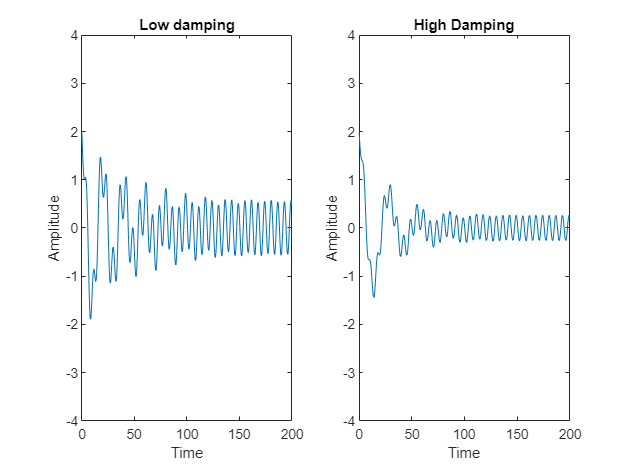


%Amp_num = matlabFunction(Amp_sym)

Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('F0'), sym('omega'), sym('C1'), sym('C2')], [20, 2, 1, 10, 1, 1, 1] );

Plots = figure('Name','Forced damped oscillations', 'NumberTitle','off');
figure(Plots)
subplot(1,2,1);
plot = fplot(Amp_num);
xlim([0 , xMax])
ylim([-4 , 4])
title("Low damping")
xlabel("Time")
ylabel('Amplitude')

Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('F0'), sym('omega'), sym('C1'), sym('C2')], [40, 2, 3, 10, 1, 1, 1] );
%pretty_equation(Amp)
subplot(1,2,2);
plot = fplot(Amp_num);
xlim([0 , xMax])
ylim([-4, 4])
title("High Damping")
xlabel("Time")
ylabel('Amplitude')


figure
disp('Oscillations stabilise faster with higher damping')

Oscillations stabilise faster with higher damping


disp('Peak amplitude also decreases with higher damping')

Peak amplitude also decreases with higher damping


Oscillations stabilise faster with higher damping

Peak amplitude also decreases with higher damping

**Washer:**

syms x(t) m k c F0 omega
m_unb = 0.5

m_unb = 0.5000

RPM = 1400

RPM = 1400


r = 0.25

r = 0.2500

M = 40

M = 40

k = 18

k = 18

c = 240

c = 240

omega = 2*pi*RPM/60

omega = 146.6077


Dx = diff(x,t)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

Dx2 = diff(x,t,2)

$$Dx2(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

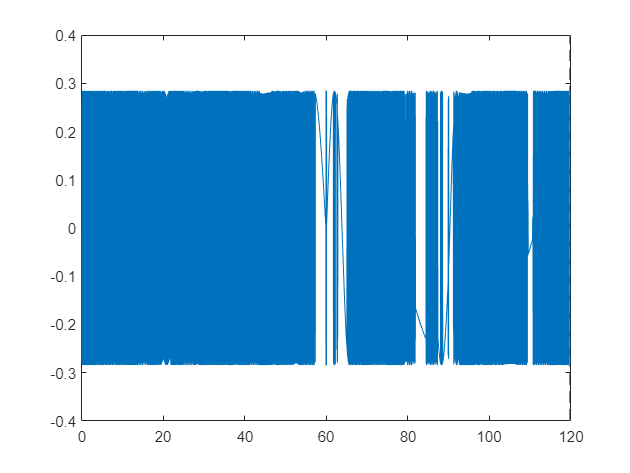

F = m*Dx2 + k*x + c*Dx == F0*sin(omega*t);

Amp_sym = dsolve(F);

F0 = m_unb*RPM^2*r;
Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('F0'), sym('omega'), sym('C1'), sym('C2')], [M, k, c, F0, omega, 0, 0] );

fplot(Amp_num)
xlim([0 , 120])
ylim([-0.4, 0.4])

**Washer with variable RPM:**

%% Variable setup
syms x(t) m k c F0 omega
m_unb = 0.5

m_unb = 0.5000

t_Max_RPM = 120

t_Max_RPM = 120

%RPM = @(t) 1400/t_Max_RPM * 
omega = RPM*2*pi/60

omega = 125.6637

r = 0.25

r = 0.2500

M = 40

M = 40

k = 9*2

k = 18

c = 120*2

c = 240


%% Equation setup
Dx = diff(x,t)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

Dx2 = diff(x,t,2)

$$Dx2(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

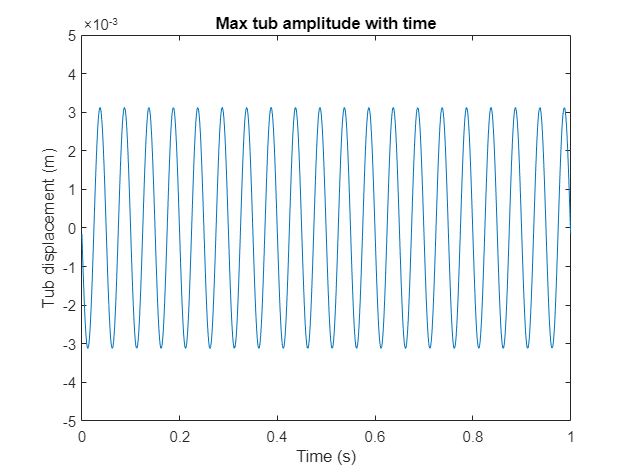



F = m*Dx2 + k*x + c*Dx == F0*sin(omega*t);

Amp_sym = dsolve(F);

F0 = m_unb*omega^2*r;
Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('F0'), sym('omega'), sym('C1'), sym('C2')], [M, k, c, F0, omega, 0, 0] );

%% Plotting

%Create a new figure to display tub displacement plot
tub_amp_plot = figure('Name','Tub_Amp_Plot', 'NumberTitle','off', 'MenuBar', 'none');

%Set figure as current figure
figure(tub_amp_plot)

%plot figure
fplot(Amp_num)

%Set axis limits
xlim([0 , 1])
ylim([-5*10^-3 , 5*10^-3])
title("Max tub amplitude with time")
xlabel('Time (s)')
ylabel('Tub displacement (m)')

**Finding intial constraints**

syms x(t) m k c F0 omega m_unb r

Dx = diff(x,t)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

Dx2 = diff(x,t,2)

$$Dx2(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

unb_force = F0 == m_unb*omega^2*r

$$unb\_force = F_{0}=m_{\mathrm{unb}}\,\omega^{2}\,r$$

F = m*Dx2 + k*x + c*Dx == F0*sin(omega*t);


cond = [x(0) == 0, Dx(0) == 0];
Amp_sym = dsolve([F, unb_force], cond)

 
Amp_sym =
 
[ empty sym ]
 


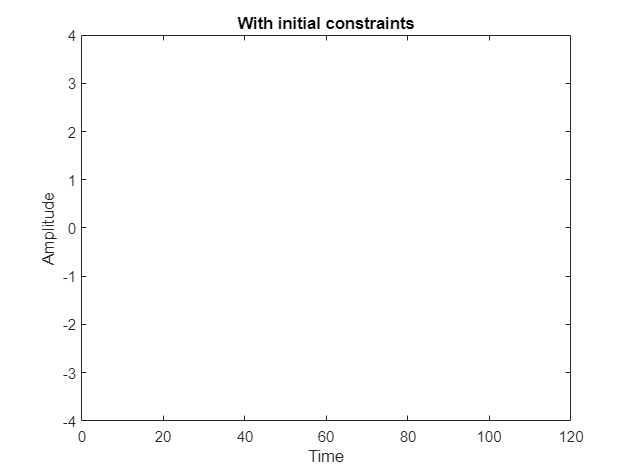


%Amp_num = matlabFunction(Amp_sym)
Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('omega'), sym('m_unb'), sym('r')], [40, 18, 240, 1400, 0.5, 0.25] );
%Amp_num = subs(Amp_sym, [sym('m'), sym('k'), sym('c'), sym('F0'), sym('omega'), sym('C1'), sym('C2')], [20, 2, 1, 10, 1, 1, 1] );

plot = fplot(Amp_num);
xlim([0 , 120])
ylim([-4 , 4])
title("With initial constraints")
xlabel("Time")
ylabel('Amplitude')